# **Modelagem pêndulo sobre rodas**

**Artigo: "DESIGN, MODELING AND CONTROL OF A TWO-WHEEL BALANCING ROBOT DRIVEN BY BLDC MOTORS" **

clear

## Modelagem 3DOF

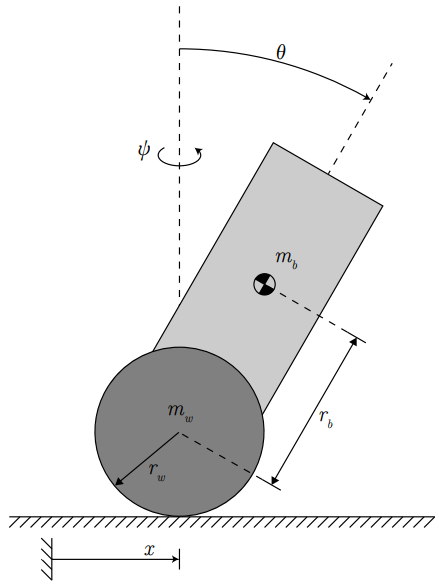

syms t x(t) theta(t) psi(t)
syms m_b r_b m_w r_w g b_theta b_x w
syms G_r s_bar V(t) Delta_V(t) V_max k

assume(m_b, "positive")
assume(r_b, "positive")
assume(m_w, "positive")
assume(r_w, "positive")
assume(b_theta, "positive")
assume(w, "positive")           % distância entre as rodas

S = syms;

### Energia potêncial

Vpot = m_b*r_b*cos(theta(t))*g

$$Vpot = g\,m_{b}\,r_{b}\,\cos\left(\theta \left(t\right)\right)$$

### Energia cinética

#### Velocidades

- **velocidade linear da roda direita**

v_c = diff([x(t);0;0]) % velocidade do centro

$$v\_c = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)\\ 0\\ 0 \end{array}\right)$$

omega_c = diff([0;0;psi(t)]) % velocidade angular do centro

$$omega\_c = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

r_wr_c = [0;-w/2;0] % raio do centro até roda direita

$$r\_wr\_c = \left(\begin{array}{c} 0\\ -\frac{w}{2}\\ 0 \end{array}\right)$$

v_wr_c = cross(omega_c, r_wr_c) % velicidade linear relativa roda direita/centro

$$v\_wr\_c = \left(\begin{array}{c} \frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2}\\ 0\\ 0 \end{array}\right)$$

v_wr = v_c + v_wr_c % velocidade linear da roda direita

$$v\_wr = \left(\begin{array}{c} \frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2}+\frac{\partial }{\partial t}x\left(t\right)\\ 0\\ 0 \end{array}\right)$$

- **velocidade linear da roda esquerda**

omega_wl = diff([0;0;psi(t)]) % velocidade angular do centro

$$omega\_wl = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

r_wl_c = [0;w/2;0] % raio do centro até roda esquerda

$$r\_wl\_c = \left(\begin{array}{c} 0\\ \frac{w}{2}\\ 0 \end{array}\right)$$

v_wl_c = cross(omega_wl, r_wl_c) % velicidade linear relativa roda esquerda/centro

$$v\_wl\_c = \left(\begin{array}{c} -\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2}\\ 0\\ 0 \end{array}\right)$$

v_wl = v_c + v_wl_c % velocidade linear da roda esquerda

$$v\_wl = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)-\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2}\\ 0\\ 0 \end{array}\right)$$

- **Velocidade angular da roda direita**

omega_wr_y =  expand([-1/r_w,0,0] * v_wr)

$$omega\_wr\_y = -\frac{\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}-\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2\,r_{w}}$$

omega_wr = [0; omega_wr_y; diff(psi(t))]

$$omega\_wr = \left(\begin{array}{c} 0\\ -\frac{\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}-\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2\,r_{w}}\\ \frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

- **Velocidade angular da roda esquerda**

omega_wl_y =  expand([1/r_w,0,0] * v_wl)

$$omega\_wl\_y = \frac{\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}-\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2\,r_{w}}$$

omega_wl = [0; omega_wl_y; diff(psi(t))]

$$omega\_wl = \left(\begin{array}{c} 0\\ \frac{\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}-\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2\,r_{w}}\\ \frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

- **Velocidade angular do corpo**

omega_b = [0; diff(theta(t)); diff(psi(t))]

$$omega\_b = \left(\begin{array}{c} 0\\ \frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

- **Velocidade linear do corpo**

v_c

$$v\_c = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)\\ 0\\ 0 \end{array}\right)$$

r_b_costheta = [r_b*sin(theta(t));0;r_b*cos(theta(t))]

$$r\_b\_costheta = \left(\begin{array}{c} r_{b}\,\sin\left(\theta \left(t\right)\right)\\ 0\\ r_{b}\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

v_b_costheta = cross(omega_b, r_b_costheta)

$$v\_b\_costheta = \left(\begin{array}{c} r_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ r_{b}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ -r_{b}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

v_b = v_c + v_b_costheta

$$v\_b = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)+r_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ r_{b}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ -r_{b}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

#### Matrizes de Inércias

syms I_wxx I_wyy I_wzz
I_w = [I_wxx 0 0; 0 I_wyy 0; 0 0 I_wzz]

$$I\_w = \left(\begin{array}{ccc} I_{\mathrm{wxx}} & 0 & 0\\ 0 & I_{\mathrm{wyy}} & 0\\ 0 & 0 & I_{\mathrm{wzz}} \end{array}\right)$$

syms I_bxx I_byy I_bzz
R_theta = [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)]

$$R\_theta(t) = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & 0 & \sin\left(\theta \left(t\right)\right)\\ 0 & 1 & 0\\ -\sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$

I_bxyz = [I_bxx 0 0; 0 I_byy 0; 0 0 I_bzz]

$$I\_bxyz = \left(\begin{array}{ccc} I_{\mathrm{bxx}} & 0 & 0\\ 0 & I_{\mathrm{byy}} & 0\\ 0 & 0 & I_{\mathrm{bzz}} \end{array}\right)$$

I_b = R_theta * I_bxyz * transpose(R_theta)

$$I\_b(t) = \begin{array}{l} \left(\begin{array}{ccc} I_{\mathrm{bxx}}\,{\cos\left(\theta \left(t\right)\right)}^{2}+I_{\mathrm{bzz}}\,{\sin\left(\theta \left(t\right)\right)}^{2} & 0 & \sigma_{1}\\ 0 & I_{\mathrm{byy}} & 0\\ \sigma_{1} & 0 & I_{\mathrm{bzz}}\,{\cos\left(\theta \left(t\right)\right)}^{2}+I_{\mathrm{bxx}}\,{\sin\left(\theta \left(t\right)\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{\mathrm{bzz}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-I_{\mathrm{bxx}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) \end{array}$$

#### Energia Cinética 

T_b_linear = 1/2*m_b*transpose(v_b)*v_b

$$T\_b\_linear = \frac{m_{b}\,{\left(\frac{\partial }{\partial t}x\left(t\right)+r_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{b}\,{r_{b}}^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}}{2}+\frac{m_{b}\,{r_{b}}^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

T_b_angular = 1/2*transpose(omega_b)*I_b*omega_b

$$T\_b\_angular(t) = \frac{\left(I_{\mathrm{bzz}}\,{\cos\left(\theta \left(t\right)\right)}^{2}+I_{\mathrm{bxx}}\,{\sin\left(\theta \left(t\right)\right)}^{2}\right)\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}}{2}+\frac{I_{\mathrm{byy}}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

T_w_linear = 1/2*m_w*transpose(v_wr)*v_wr + 1/2*m_w*transpose(v_wl)*v_wl

$$T\_w\_linear = \frac{m_{w}\,{\left(\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2}-\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}+\frac{m_{w}\,{\left(\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2}+\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}$$

T_w_angular = 1/2*transpose(omega_wr)*I_w*omega_wr + 1/2*transpose(omega_wl)*I_w*omega_wl

$$T\_w\_angular = \begin{array}{l} I_{\mathrm{wzz}}\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}+I_{\mathrm{wyy}}\,\left(\frac{\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}-\sigma_{2}\right)\,\left(\frac{\frac{\partial }{\partial t}x\left(t\right)}{2\,r_{w}}-\sigma_{1}\right)+I_{\mathrm{wyy}}\,\left(\frac{\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}+\sigma_{2}\right)\,\left(\frac{\frac{\partial }{\partial t}x\left(t\right)}{2\,r_{w}}+\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{4\,r_{w}}\\ \sigma_{2}=\frac{w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2\,r_{w}} \end{array}$$

T = T_b_linear + T_b_angular + T_w_linear + T_w_angular;
T = simplify(T)

$$T(t) = \begin{array}{l} \frac{4\,I_{\mathrm{wyy}}\,\sigma_{3}+2\,I_{\mathrm{bxx}}\,{r_{w}}^{2}\,\sigma_{1}+4\,I_{\mathrm{wzz}}\,{r_{w}}^{2}\,\sigma_{1}+2\,I_{\mathrm{byy}}\,{r_{w}}^{2}\,\sigma_{4}+I_{\mathrm{wyy}}\,w^{2}\,\sigma_{1}+2\,m_{b}\,{r_{w}}^{2}\,\sigma_{3}+4\,m_{w}\,{r_{w}}^{2}\,\sigma_{3}-2\,I_{\mathrm{bxx}}\,{r_{w}}^{2}\,\sigma_{2}\,\sigma_{1}+2\,I_{\mathrm{bzz}}\,{r_{w}}^{2}\,\sigma_{2}\,\sigma_{1}+2\,m_{b}\,{r_{b}}^{2}\,{r_{w}}^{2}\,\sigma_{1}+2\,m_{b}\,{r_{b}}^{2}\,{r_{w}}^{2}\,\sigma_{4}+m_{w}\,{r_{w}}^{2}\,w^{2}\,\sigma_{1}-2\,m_{b}\,{r_{b}}^{2}\,{r_{w}}^{2}\,\sigma_{2}\,\sigma_{1}+4\,m_{b}\,r_{b}\,{r_{w}}^{2}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{4\,{r_{w}}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\\ \sigma_{2}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{3}={\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

- **Agrupamento de termos**

coeffs_dx = coeffs(T, diff(x));
coeffs_dx = coeffs_dx(t);
coeffs_dx_2 = coeffs_dx(3); % coeficientes de diff(x)^2
m_x = coeffs_dx_2 * 2 % massa equivalente -> 1/2 m * (dx/dt)^2

$$m\_x = \frac{4\,I_{\mathrm{wyy}}+2\,m_{b}\,{r_{w}}^{2}+4\,m_{w}\,{r_{w}}^{2}}{2\,{r_{w}}^{2}}$$

coeffs_dtheta = coeffs(T, diff(theta));
coeffs_dtheta = coeffs_dtheta(t);
coeffs_dtheta_2 = coeffs_dtheta(3); % coeficientes de diff(theta)^2
I_theta = coeffs_dtheta_2 * 2 % massa equivalente -> 1/2 I * (dtheta/dt)^2

$$I\_theta = \frac{2\,m_{b}\,{r_{b}}^{2}\,{r_{w}}^{2}+2\,I_{\mathrm{byy}}\,{r_{w}}^{2}}{2\,{r_{w}}^{2}}$$

I_theta = simplify(I_theta)

$$I\_theta = m_{b}\,{r_{b}}^{2}+I_{\mathrm{byy}}$$

coeffs_dpsi = coeffs(T, diff(psi));
coeffs_dpsi = coeffs_dpsi(t);
coeffs_dpsi_2 = coeffs_dpsi(2); % coeficientes de diff(psi)^2 (não tem termo de grau 1)
I_psi_theta = coeffs_dpsi_2 * 2 % massa equivalente -> 1/2 I * (dpsi/dt)^2

$$I\_psi\_theta = \begin{array}{l} \frac{2\,I_{\mathrm{bxx}}\,{r_{w}}^{2}+4\,I_{\mathrm{wzz}}\,{r_{w}}^{2}+I_{\mathrm{wyy}}\,w^{2}-2\,I_{\mathrm{bxx}}\,{r_{w}}^{2}\,\sigma_{1}+2\,I_{\mathrm{bzz}}\,{r_{w}}^{2}\,\sigma_{1}+2\,m_{b}\,{r_{b}}^{2}\,{r_{w}}^{2}+m_{w}\,{r_{w}}^{2}\,w^{2}-2\,m_{b}\,{r_{b}}^{2}\,{r_{w}}^{2}\,\sigma_{1}}{2\,{r_{w}}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\theta \left(t\right)\right)}^{2} \end{array}$$

I_psi = subs(I_psi_theta, [sin(theta), cos(theta)], [0, 0])

$$I\_psi = \frac{2\,I_{\mathrm{bxx}}\,{r_{w}}^{2}+4\,I_{\mathrm{wzz}}\,{r_{w}}^{2}+I_{\mathrm{wyy}}\,w^{2}+2\,m_{b}\,{r_{b}}^{2}\,{r_{w}}^{2}+m_{w}\,{r_{w}}^{2}\,w^{2}}{2\,{r_{w}}^{2}}$$

T_others = simplify(T - 1/2*m_x*diff(x)^2 - 1/2*I_theta*diff(theta)^2 - 1/2*I_psi*diff(psi)^2)

$$T\_others(t) = \begin{array}{l} \frac{I_{\mathrm{bzz}}\,\sigma_{1}\,\sigma_{2}}{2}-\frac{I_{\mathrm{bxx}}\,\sigma_{1}\,\sigma_{2}}{2}-\frac{m_{b}\,{r_{b}}^{2}\,\sigma_{1}\,\sigma_{2}}{2}+m_{b}\,r_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2} \end{array}$$

b_m_x = m_x;
b_I_theta = I_theta;
b_I_psi = I_psi;
syms m_x I_theta I_psi
T_simply = 1/2*m_x*diff(x)^2 + 1/2*I_theta*diff(theta)^2 + 1/2*I_psi*diff(psi)^2 + T_others;
T_simply = simplify(T_simply)

$$T\_simply(t) = \begin{array}{l} \frac{I_{\psi }\,\sigma_{1}}{2}+\frac{I_{\theta }\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{x}\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}-\frac{I_{\mathrm{bxx}}\,\sigma_{2}\,\sigma_{1}}{2}+\frac{I_{\mathrm{bzz}}\,\sigma_{2}\,\sigma_{1}}{2}-\frac{m_{b}\,{r_{b}}^{2}\,\sigma_{2}\,\sigma_{1}}{2}+m_{b}\,r_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\\ \sigma_{2}={\cos\left(\theta \left(t\right)\right)}^{2} \end{array}$$

### Lagrangiano

L = T_simply - Vpot

$$L(t) = \begin{array}{l} \frac{I_{\psi }\,\sigma_{1}}{2}+\frac{I_{\theta }\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m_{x}\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}-\frac{I_{\mathrm{bxx}}\,\sigma_{2}\,\sigma_{1}}{2}+\frac{I_{\mathrm{bzz}}\,\sigma_{2}\,\sigma_{1}}{2}-\frac{m_{b}\,{r_{b}}^{2}\,\sigma_{2}\,\sigma_{1}}{2}-g\,m_{b}\,r_{b}\,\cos\left(\theta \left(t\right)\right)+m_{b}\,r_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\\ \sigma_{2}={\cos\left(\theta \left(t\right)\right)}^{2} \end{array}$$

#### Torque para Tensão

omega_ml = expand(omega_wl_y - omega_b(2))*G_r;
omega_mr = expand(omega_wr_y + omega_b(2))*G_r;
syms V_l(t) V_r(t)
% V_l = V + Delta_V;
% V_r = -(V - Delta_V);

T_ml = expand(G_r*(s_bar*V_l/V_max - k*omega_ml))

$$T\_ml(t) = {G_{r}}^{2}\,k\,\frac{\partial }{\partial t}\theta \left(t\right)-\frac{{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}+\frac{G_{r}\,\bar{s}\,V_{l}\left(t\right)}{V_{\max}}+\frac{{G_{r}}^{2}\,k\,w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2\,r_{w}}$$

T_mr = expand(G_r*(s_bar*V_r/V_max - k*omega_mr))

$$T\_mr(t) = \frac{{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}-{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{G_{r}\,\bar{s}\,V_{r}\left(t\right)}{V_{\max}}+\frac{{G_{r}}^{2}\,k\,w\,\frac{\partial }{\partial t}\psi \left(t\right)}{2\,r_{w}}$$


$$\frac{d}{dt} \bigg( \frac{\partial L}{\partial \dot{x}} \bigg) -  \frac{\partial L}{\partial x} = Q_x$$


Q_x = -(T_mr - T_ml)/r_w

$$Q\_x(t) = \frac{2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}\theta \left(t\right)-\frac{2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}+\frac{G_{r}\,\bar{s}\,V_{l}\left(t\right)}{V_{\max}}-\frac{G_{r}\,\bar{s}\,V_{r}\left(t\right)}{V_{\max}}}{r_{w}}$$

Eqn1 = diff(diff(L,diff(x)),t) - diff(L,x) == Q_x

$$Eqn1(t) = m_{x}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-m_{b}\,r_{b}\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+m_{b}\,r_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}\theta \left(t\right)-\frac{2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}+\frac{G_{r}\,\bar{s}\,V_{l}\left(t\right)}{V_{\max}}-\frac{G_{r}\,\bar{s}\,V_{r}\left(t\right)}{V_{\max}}}{r_{w}}$$


$$\frac{d}{dt} \bigg( \frac{\partial L}{\partial \dot{\theta}} \bigg) -  \frac{\partial L}{\partial \theta} = Q_\theta$$


Q_theta = T_mr - T_ml

$$Q\_theta(t) = \frac{2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}-2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}\theta \left(t\right)-\frac{G_{r}\,\bar{s}\,V_{l}\left(t\right)}{V_{\max}}+\frac{G_{r}\,\bar{s}\,V_{r}\left(t\right)}{V_{\max}}$$

Eqn2 = diff(diff(L,diff(theta)),t) - diff(L,theta) == Q_theta

$$Eqn2(t) = \begin{array}{l} I_{\theta }\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-g\,m_{b}\,r_{b}\,\sin\left(\theta \left(t\right)\right)-I_{\mathrm{bxx}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+I_{\mathrm{bzz}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+m_{b}\,r_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-m_{b}\,{r_{b}}^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}=\frac{2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}x\left(t\right)}{r_{w}}-2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}\theta \left(t\right)-\frac{G_{r}\,\bar{s}\,V_{l}\left(t\right)}{V_{\max}}+\frac{G_{r}\,\bar{s}\,V_{r}\left(t\right)}{V_{\max}}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2} \end{array}$$


$$\frac{d}{dt} \bigg( \frac{\partial L}{\partial \dot{\psi}} \bigg) -  \frac{\partial L}{\partial \psi} = Q_\psi$$


Q_psi = w/(2*r_w) * -(T_mr + T_ml)

$$Q\_psi(t) = -\frac{w\,\left(\frac{G_{r}\,\bar{s}\,V_{l}\left(t\right)}{V_{\max}}+\frac{G_{r}\,\bar{s}\,V_{r}\left(t\right)}{V_{\max}}+\frac{{G_{r}}^{2}\,k\,w\,\frac{\partial }{\partial t}\psi \left(t\right)}{r_{w}}\right)}{2\,r_{w}}$$

Eqn3 = diff(diff(L,diff(psi)),t) - diff(L,psi) == Q_psi

$$Eqn3(t) = \begin{array}{l} I_{\psi }\,\sigma_{1}-I_{\mathrm{bxx}}\,\sigma_{2}\,\sigma_{1}+I_{\mathrm{bzz}}\,\sigma_{2}\,\sigma_{1}-m_{b}\,{r_{b}}^{2}\,\sigma_{2}\,\sigma_{1}+2\,I_{\mathrm{bxx}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)-2\,I_{\mathrm{bzz}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)+2\,m_{b}\,{r_{b}}^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)=-\frac{w\,\left(\frac{G_{r}\,\bar{s}\,V_{l}\left(t\right)}{V_{\max}}+\frac{G_{r}\,\bar{s}\,V_{r}\left(t\right)}{V_{\max}}+\frac{{G_{r}}^{2}\,k\,w\,\frac{\partial }{\partial t}\psi \left(t\right)}{r_{w}}\right)}{2\,r_{w}}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right)\\ \sigma_{2}={\cos\left(\theta \left(t\right)\right)}^{2} \end{array}$$

#### Equações da aceleração

Eqn = [Eqn1; Eqn2; Eqn3]

q = [x; theta; psi]

$$q(t) = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \psi \left(t\right) \end{array}\right)$$

[Eqn_fo, q_fo] = reduceDifferentialOrder(Eqn, q);

#### Mass Matrix

[M, F] = massMatrixForm(Eqn_fo, q_fo)

$$M = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & m_{x} & m_{b}\,r_{b}\,\cos\left(\theta \left(t\right)\right) & 0\\ 0 & 0 & 0 & m_{b}\,r_{b}\,\cos\left(\theta \left(t\right)\right) & I_{\theta } & 0\\ 0 & 0 & 0 & 0 & 0 & I_{\psi }-I_{\mathrm{bxx}}\,\sigma_{1}+I_{\mathrm{bzz}}\,\sigma_{1}-m_{b}\,{r_{b}}^{2}\,\sigma_{1}\\ -1 & 0 & 0 & 0 & 0 & 0\\ 0 & -1 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\theta \left(t\right)\right)}^{2} \end{array}$$

$$F = \begin{array}{l} \left(\begin{array}{c} \frac{\sigma_{4}+\sigma_{2}-\sigma_{1}-\sigma_{3}}{r_{w}}+m_{b}\,r_{b}\,\sin\left(\theta \left(t\right)\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}\\ g\,m_{b}\,r_{b}\,\sin\left(\theta \left(t\right)\right)-\sigma_{4}+I_{\mathrm{bxx}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{{\mathrm{Dpsi}}_{t}\left(t\right)}^{2}-I_{\mathrm{bzz}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{{\mathrm{Dpsi}}_{t}\left(t\right)}^{2}-\sigma_{2}+\sigma_{1}+\sigma_{3}+m_{b}\,{r_{b}}^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{{\mathrm{Dpsi}}_{t}\left(t\right)}^{2}\\ 2\,I_{\mathrm{bzz}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\mathrm{Dpsi}}_{t}\left(t\right)\,\mathrm{Dthetat}\left(t\right)-2\,I_{\mathrm{bxx}}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\mathrm{Dpsi}}_{t}\left(t\right)\,\mathrm{Dthetat}\left(t\right)-\frac{w\,\left(\sigma_{2}+\sigma_{1}+\frac{{G_{r}}^{2}\,k\,w\,{\mathrm{Dpsi}}_{t}\left(t\right)}{r_{w}}\right)}{2\,r_{w}}-2\,m_{b}\,{r_{b}}^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\mathrm{Dpsi}}_{t}\left(t\right)\,\mathrm{Dthetat}\left(t\right)\\ -\mathrm{Dxt}\left(t\right)\\ -\mathrm{Dthetat}\left(t\right)\\ -{\mathrm{Dpsi}}_{t}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{G_{r}\,\bar{s}\,V_{r}\left(t\right)}{V_{\max}}\\ \sigma_{2}=\frac{G_{r}\,\bar{s}\,V_{l}\left(t\right)}{V_{\max}}\\ \sigma_{3}=\frac{2\,{G_{r}}^{2}\,k\,\mathrm{Dxt}\left(t\right)}{r_{w}}\\ \sigma_{4}=2\,{G_{r}}^{2}\,k\,\mathrm{Dthetat}\left(t\right) \end{array}$$

f = simplify(M \ F)

#### Linearization

q_0 = [0 0 0 0 0 0]';

States = q_fo

$$States = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \psi \left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right)\\ {\mathrm{Dpsi}}_{t}\left(t\right) \end{array}\right)$$

% Inputs = [V; Delta_V]
Inputs = [V_l; V_r]

$$Inputs(t) = \left(\begin{array}{c} V_{l}\left(t\right)\\ V_{r}\left(t\right) \end{array}\right)$$

A = simplify(subs(jacobian(f, States), States, q_0))

$$A = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & -\frac{g\,{m_{b}}^{2}\,{r_{b}}^{2}}{\sigma_{1}} & 0 & -\frac{\sigma_{3}}{{r_{w}}^{2}\,\sigma_{1}} & \frac{\sigma_{3}}{r_{w}\,\sigma_{1}} & 0\\ 0 & \frac{g\,m_{b}\,m_{x}\,r_{b}}{\sigma_{1}} & 0 & \frac{\sigma_{2}}{{r_{w}}^{2}\,\sigma_{1}} & -\frac{\sigma_{2}}{r_{w}\,\sigma_{1}} & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{{G_{r}}^{2}\,k\,w^{2}}{2\,{r_{w}}^{2}\,\left(m_{b}\,{r_{b}}^{2}+I_{\mathrm{bxx}}-I_{\mathrm{bzz}}-I_{\psi }\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{\theta }\,m_{x}-{m_{b}}^{2}\,{r_{b}}^{2}\\ \sigma_{2}=2\,{G_{r}}^{2}\,k\,\left(m_{b}\,r_{b}+m_{x}\,r_{w}\right)\\ \sigma_{3}=2\,{G_{r}}^{2}\,k\,\left(I_{\theta }+m_{b}\,r_{b}\,r_{w}\right) \end{array}$$

B = simplify(subs(jacobian(f, Inputs(t)), States, q_0))

$$B = \begin{array}{l} \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ \sigma_{2} & -\sigma_{2}\\ -\sigma_{1} & \sigma_{1}\\ \frac{G_{r}\,\bar{s}\,w}{2\,V_{\max}\,r_{w}\,\left(m_{b}\,{r_{b}}^{2}+I_{\mathrm{bxx}}-I_{\mathrm{bzz}}-I_{\psi }\right)} & \frac{G_{r}\,\bar{s}\,w}{2\,V_{\max}\,r_{w}\,\left(m_{b}\,{r_{b}}^{2}+I_{\mathrm{bxx}}-I_{\mathrm{bzz}}-I_{\psi }\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{G_{r}\,\bar{s}\,\left(m_{b}\,r_{b}+m_{x}\,r_{w}\right)}{V_{\max}\,r_{w}\,\left(I_{\theta }\,m_{x}-{m_{b}}^{2}\,{r_{b}}^{2}\right)}\\ \sigma_{2}=\frac{G_{r}\,\bar{s}\,\left(I_{\theta }+m_{b}\,r_{b}\,r_{w}\right)}{V_{\max}\,r_{w}\,\left(I_{\theta }\,m_{x}-{m_{b}}^{2}\,{r_{b}}^{2}\right)} \end{array}$$

B = B * [1 1; -1 1]

$$B = \begin{array}{l} \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ \frac{2\,G_{r}\,\bar{s}\,\left(I_{\theta }+m_{b}\,r_{b}\,r_{w}\right)}{\sigma_{1}} & 0\\ -\frac{2\,G_{r}\,\bar{s}\,\left(m_{b}\,r_{b}+m_{x}\,r_{w}\right)}{\sigma_{1}} & 0\\ 0 & \frac{G_{r}\,\bar{s}\,w}{V_{\max}\,r_{w}\,\left(m_{b}\,{r_{b}}^{2}+I_{\mathrm{bxx}}-I_{\mathrm{bzz}}-I_{\psi }\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=V_{\max}\,r_{w}\,\left(I_{\theta }\,m_{x}-{m_{b}}^{2}\,{r_{b}}^{2}\right) \end{array}$$

Inputs = [V; Delta_V]

$$Inputs(t) = \left(\begin{array}{c} V\left(t\right)\\ \Delta_{V}\left(t\right) \end{array}\right)$$

C = sym(eye(6))

$$C = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

## Valores Númericos

load("Parametros.mat")

r_w = 0.03;
r_b = 0.08;
w = 12e-2;
m_w = 12e-3;
m_b = 216e-3;
g = 9.81;
G_r = 30;
V_max = 7.4;

s_bar = s_t;

I_wyy = I_w;
I_wxx = I_wyy/2;
I_wzz = I_wyy/2;

I_byy = I_b;
I_bxx = I_byy;
I_bzz = I_byy/2;

format shortE
I_theta = double(subs(b_I_theta))

I_theta =    2.1566e-03


I_psi = double(subs(b_I_psi))

I_psi =    3.0593e-03


m_x = double(subs(b_m_x))

m_x =    4.4155e-01


format default

### Função linear

A, B, C

$$A = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & -\frac{g\,{m_{b}}^{2}\,{r_{b}}^{2}}{\sigma_{1}} & 0 & -\frac{\sigma_{3}}{{r_{w}}^{2}\,\sigma_{1}} & \frac{\sigma_{3}}{r_{w}\,\sigma_{1}} & 0\\ 0 & \frac{g\,m_{b}\,m_{x}\,r_{b}}{\sigma_{1}} & 0 & \frac{\sigma_{2}}{{r_{w}}^{2}\,\sigma_{1}} & -\frac{\sigma_{2}}{r_{w}\,\sigma_{1}} & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{{G_{r}}^{2}\,k\,w^{2}}{2\,{r_{w}}^{2}\,\left(m_{b}\,{r_{b}}^{2}+I_{\mathrm{bxx}}-I_{\mathrm{bzz}}-I_{\psi }\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{\theta }\,m_{x}-{m_{b}}^{2}\,{r_{b}}^{2}\\ \sigma_{2}=2\,{G_{r}}^{2}\,k\,\left(m_{b}\,r_{b}+m_{x}\,r_{w}\right)\\ \sigma_{3}=2\,{G_{r}}^{2}\,k\,\left(I_{\theta }+m_{b}\,r_{b}\,r_{w}\right) \end{array}$$

$$B = \begin{array}{l} \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ \frac{2\,G_{r}\,\bar{s}\,\left(I_{\theta }+m_{b}\,r_{b}\,r_{w}\right)}{\sigma_{1}} & 0\\ -\frac{2\,G_{r}\,\bar{s}\,\left(m_{b}\,r_{b}+m_{x}\,r_{w}\right)}{\sigma_{1}} & 0\\ 0 & \frac{G_{r}\,\bar{s}\,w}{V_{\max}\,r_{w}\,\left(m_{b}\,{r_{b}}^{2}+I_{\mathrm{bxx}}-I_{\mathrm{bzz}}-I_{\psi }\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=V_{\max}\,r_{w}\,\left(I_{\theta }\,m_{x}-{m_{b}}^{2}\,{r_{b}}^{2}\right) \end{array}$$

$$C = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

An = double(subs(A))

An =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -4.4814         0  -11.3179    0.3395         0
         0  114.5125         0  129.1583   -3.8747         0
         0         0         0         0         0   -7.7192


Bn = double(subs(B))

Bn =          0         0
         0         0
         0         0
    1.5267         0
  -17.4221         0
         0  -17.3540


Cn = double(C)

Cn =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


### Função não linear

fn = subs(f)

syms(S)

## Exportar

save("modelo8", "fn", "An", "Bn", "Cn", "States", "Inputs", "q_fo")